## Objective

## Plt and Visualize 2-D Circulant Matrix

[Source](https://www.mathworks.com/matlabcentral/answers/339470-how-to-write-a-circulant-matrix-where-the-elements-are-matrices-thanks)

% Supposing the matrices you want to use in a circulant pattern are 
% stored as a M x N x K array (where M x N is the size of each individual matrix block 
% and you want a K x K circulant pattern)

M = 2;
N = 3;
K = 4;
% Original matrix
A = randn(M,N,K);
% Coefficients for block circulant
Ac = permute(A, [1 3 2]);
Ac = cat(2, Ac(:, 2:K, :), Ac);
% Create the block-circulant matrix using convn
I = reshape(eye(K), [1 K 1 K]);
C = convn(I, Ac);
C = reshape(C(:, K:(2*K-1), :, :), [M*K, N*K]);
disp(C);

    0.5939   -1.3270    0.4018   -2.0220    0.6125   -1.1187    1.5163    1.6360    0.5894   -0.3268    0.5455    0.3975
   -2.1860   -1.4410    1.4702   -0.9821   -0.0549   -0.6264   -0.0326   -0.4251   -0.0628    0.8123   -1.0516   -0.7519
   -0.3268    0.5455    0.3975    0.5939   -1.3270    0.4018   -2.0220    0.6125   -1.1187    1.5163    1.6360    0.5894
    0.8123   -1.0516   -0.7519   -2.1860   -1.4410    1.4702   -0.9821   -0.0549   -0.6264   -0.0326   -0.4251   -0.0628
    1.5163    1.6360    0.5894   -0.3268    0.5455    0.3975    0.5939   -1.3270    0.4018   -2.0220    0.6125   -1.1187
   -0.0326   -0.4251   -0.0628    0.8123   -1.0516   -0.7519   -2.1860   -1.4410    1.4702   -0.9821   -0.0549   -0.6264
   -2.0220    0.6125   -1.1187    1.5163    1.6360    0.5894   -0.3268    0.5455    0.3975    0.5939   -1.3270    0.4018
   -0.9821   -0.0549   -0.6264   -0.0326   -0.4251   -0.0628    0.8123   -1.0516   -0.7519   -2.1860   -1.4410    1.4702



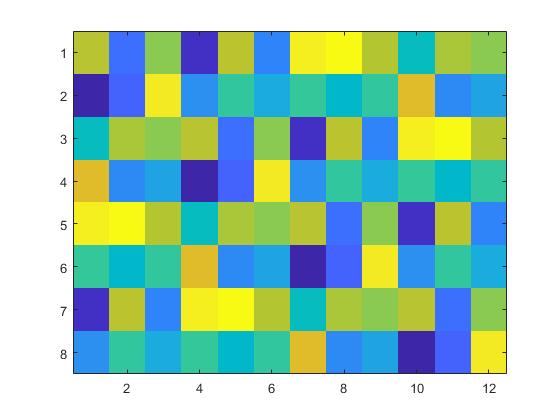

imagesc(C);